**Instituto Politécnico Nacional**

**Unidad Profesional Interdisciplinaria en Ingeniería y Tecnologías Avanzadas**

**Integración de un Sistema Robótico**

# Seguimiento de Trayectoria con Robot Antropomórfico

Equipo 6:

- Fierro De La Rosa Abril Evangelina

- Islas Estrada Luis Rafael

- Luna Reyes Rodrigo

- Montero Rasgado Josué Emiliano

## Robot Puma

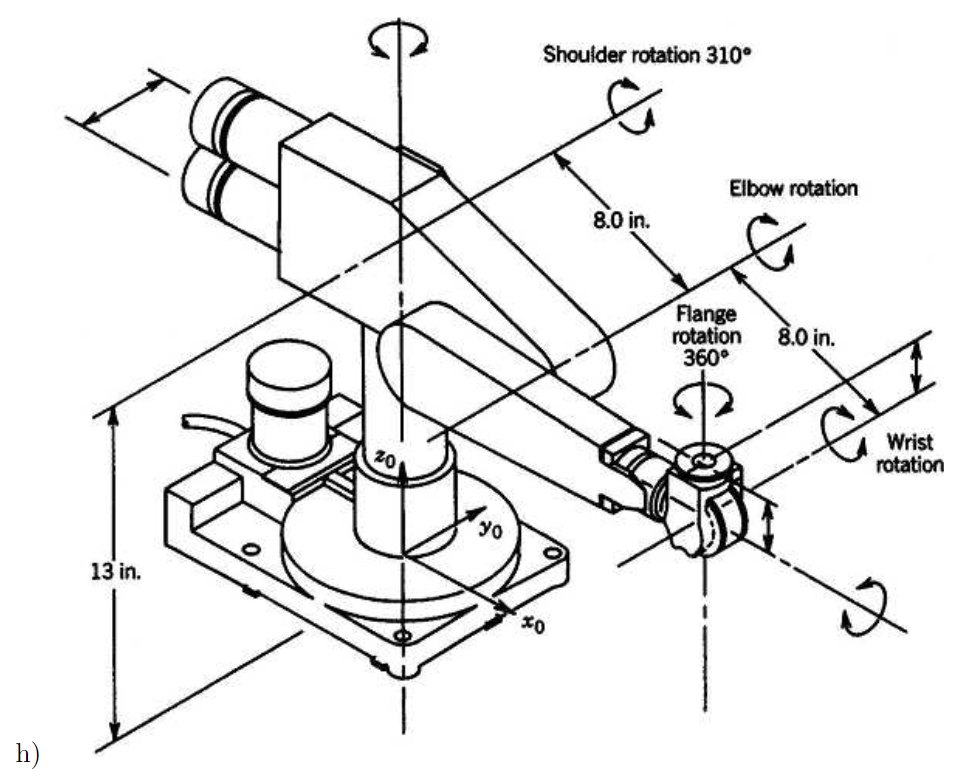

## **Cinemática Directa**

## **Cinemática Inversa**

- **Paso 1:** Se asignan los ejes $z_0, z_1, z_2, z_3, z_4, z_5$ como los ejes de rotación de $q_1, q_2, q_3, q_4, q_5, q_6$.

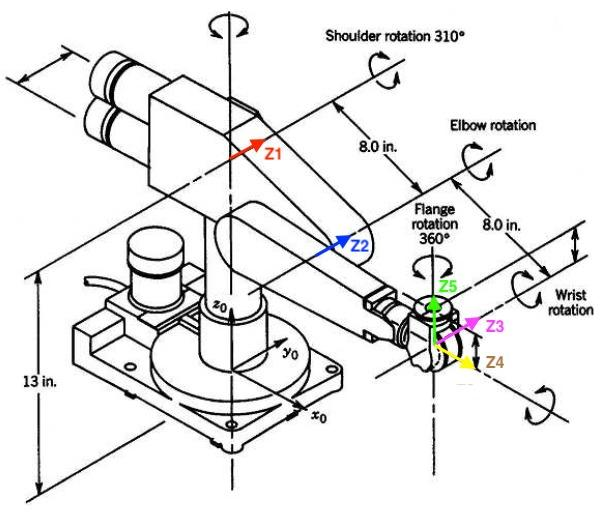

- **Paso 2: **Para el origen $O_0$, se usa la referencia brindada por el diagrama.

- **Pasos 3-5: **Dado que $z_1$ es perpendicular a $z_0$, el marco $O_1$ se coloca en el punto de intersección entre ambos ejes. Para $O_2$ se usa como referencia la distancia física entre los ejes de giro $z_1$ y $z_2$, además de considerar que, dada la anchura de los eslabones, existe una distancia $d_1$ que separa a ambos marcos en dirección de sus ejes $z$. 

- **Paso 6: **Finalmente, dado que los ejes $z_3, z_4, z_5$, son perpendiculares entre sí y se intersectan en el mismo punto se decide colocar un mismo origen $O$ para las tres juntas (sin olvidar las distancias que existen entre las juntas en el diagrama).

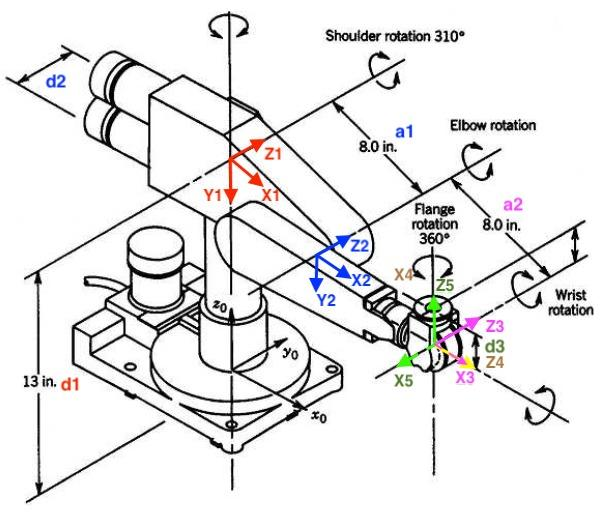

De esta forma, la tabla de parámetros de Denavit Hartenberg queda de la siguiente forma:

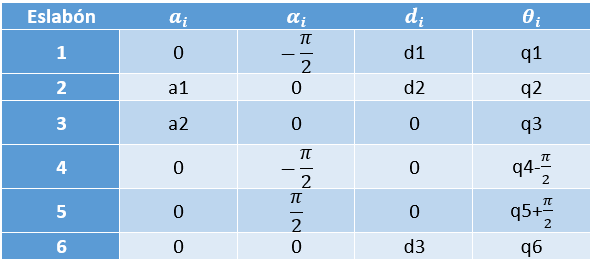

clc; clear; close all;
syms a1 a2 d1 d2 d3 d4 a alpha d theta q1 q2 q3 q4 q5 q6

A(a, alpha, d, theta) = [cos(theta) -sin(theta)*cos(alpha) sin(theta)*sin(alpha) a*cos(theta);
    sin(theta) cos(theta)*cos(alpha) -cos(theta)*sin(alpha) a*sin(theta);
    0 sin(alpha) cos(alpha) d;
    0 0 0 1]

Por lo que las matrices de transformación quedan así:

A1 = A(0, -pi/2, d1, q1)
A2 = A(a1, 0, d2, q2)
A3 = A(a2, 0, 0, q3)
A4 = A(0, -pi/2, 0, q4-pi/2)
A5 = A(0, pi/2, 0, q5+pi/2)
A6 = A(0, 0, d3, q6)

Multiplicando estas matrices obtenemos la matriz de transfroamción del robot completo $T^0_6$.

T06 = A1*A2*A3*simplify(A4)*simplify(A5)*A6;
R06 = simplify(T06(1:3,1:3),10)
D06 = simplify(T06(1:3,4),10)